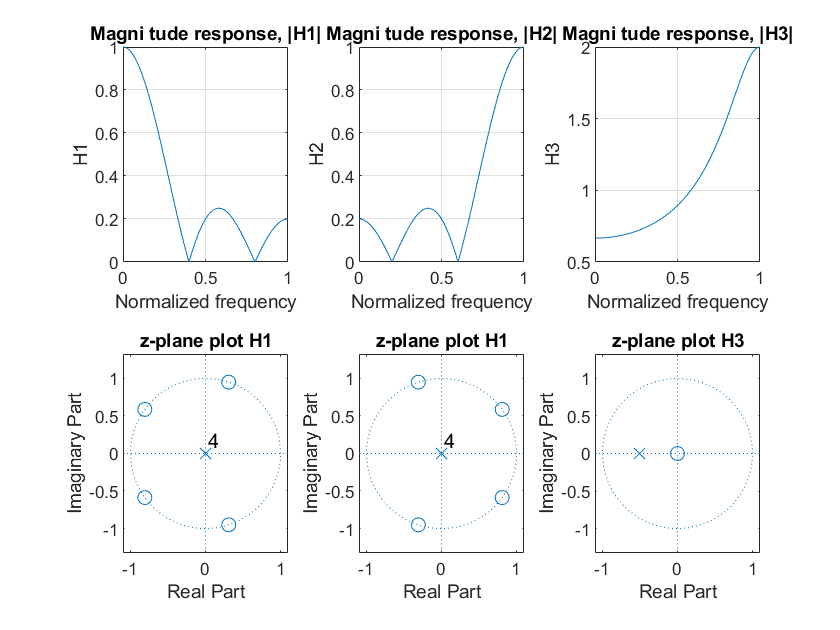

% Group-6

N=1024; 
%System 1 
 b1=[0.2 0.2 0.2 0.2 0.2];  % coefficients (Num.) of transfer function system 1    
a1=[1 0 0 0 0];	 	        % Coefficients (Den.) of transfer function System 1
root1_num= roots(b1);  	 	 % Using roots function
root1_Den= roots(a1);         % Using roots function
[H1,W1]=freqz(b1,a1,N);          % Use freqz function: [H, W] = FREQZ (B, A, N) ; with N=1024

%system2
b2=[0.2 -0.2 0.2 -0.2 0.2];    
a2=[1 0 0 0 0];	 	
root2_num= roots(b2) ; 	 	
root2_Den= roots(a2);
[H2,W2]=freqz(b2,a2,N);

%System 3
b3=[1 0];                      
a3=[1 0.5];                    
root3_num=roots(b3) ;                  
 root3_Den=roots(a3);
 [H3,W3]=freqz(b3,a3,N);
 
 
 %% z-plane and magnitude response plots
 
 %System 1
 subplot(2,3,1)
 plot (W1/pi, abs(H1)); %use subplot
 title ('Magni tude response, |H1|');
 xlabel ('Normalized frequency');
 ylabel ('H1');
 grid on;
  subplot(2,3,4)
 zplane(root1_num,root1_Den); %use subplot
 title ('z-plane plot H1');
 
 %system2
 subplot(2,3,2)
 plot (W2/pi, abs(H2)); %use subplot
 title ('Magni tude response, |H2|');
 xlabel ('Normalized frequency');
 ylabel ('H2');
 grid on;
  subplot(2,3,5)
 zplane(root2_num,root2_Den); %use subplot
 title ('z-plane plot H1');
 
  %system3
 subplot(2,3,3)
 plot (W3/pi, abs(H3)); %use subplot
 title ('Magni tude response, |H3|');
 xlabel ('Normalized frequency'); 
 ylabel ('H3');
 grid on;
  subplot(2,3,6)
 zplane(root3_num,root3_Den); %use subplot
 title ('z-plane plot H3');